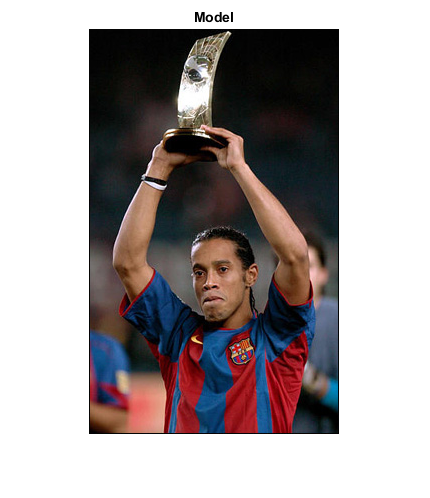

im = imread('model.jpg');
figure, imshow(im); title('Model');

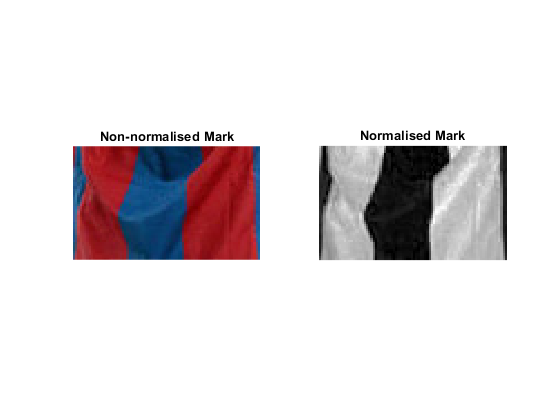


pattern = im(350:400,87:170,:);
figure, 
subplot(1,2,1);imshow(pattern); title('Non-normalised Mark');

imnorm = normalizeRGB(im);
pattnorm = imnorm(350:400,87:170,:);
subplot(1,2,2);imshow(pattnorm(:,:,1)); title('Normalised Mark');

[model_red, model_blue] = histcountRB(pattnorm,30);

%figure, [model_red, model_blue] = histcountRB(pattnorm, 30); title('Histograma Red & Blue model');

Passem totes les imatges del barça (menys la que utilitzem com a model) per a extreure la similitud de cadascuna amb el model.

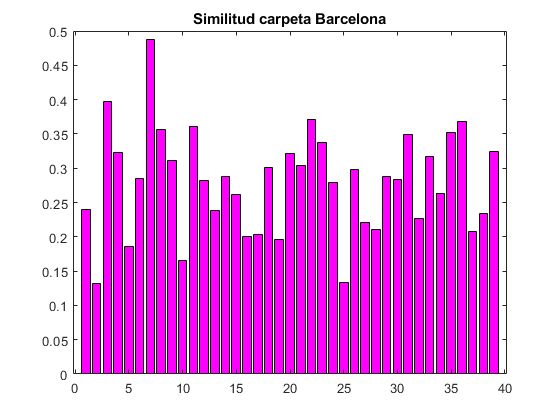

y = zeros(1,39);

for i = 1:39
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novanorm = normalizeRGB(novaim);    
    [red, blue] = computeQuadrants(model_red, model_blue, novanorm, 30, 0, 2, 2);
    rb = (red+blue)/2;
    y(i) = rb;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

for i = 1:size(y)
    if y(i) < 0.5
        b(i).CData = [1 0 1];
    end
end

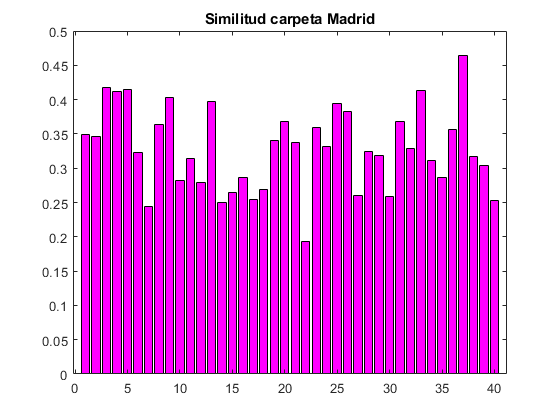

y = zeros(1,40);

for i = 1:40
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    novanorm = normalizeRGB(novaim);    
    [red, blue] = computeQuadrants(model_red, model_blue, novanorm, 30, 0, 2, 2);
    rb = (red+blue)/2;
    y(i) = rb;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

for i = 1:size(y)
    if y(i) < 0.5
        b(i).CData = [1 0 1];
    end
end